[x, y] = meshgrid(-2:0.05:3,-3.7:0.05:1.3);
fx = 0;
fy = 0;
v = 0;
wallScale = 1;

for a = -1.5:0.169:2.5
    v = v - log(sqrt((x-a).^2+(y-1).^2));
    fx = fx - wallScale*((x-a)./((x-a).^2+(y-1).^2));
    fy = fy - wallScale*((y-1)./((x-a).^2+(y-1).^2));
end

for a = -3.37:0.1:1
    v = v - log(sqrt((x-2.5).^2+(y-a).^2));
    fx = fx - wallScale*((x-2.5)./((x-2.5).^2+(y-a).^2));
    fy = fy - wallScale*((y-a)./((x-2.5).^2+(y-a).^2));
end

for a = -1.5:0.1:2.5
    v = v - log(sqrt((x-a).^2+(y+3.37).^2));
    fx = fx - wallScale*((x-a)./((x-a).^2+(y+3.37).^2));
    fy = fy - wallScale*((y+3.37)./((x-a).^2+(y+3.37).^2));
end

for a = -3.37:0.1:1
    v = v - log(sqrt((x+1.5).^2+(y-a).^2));
    fx = fx - wallScale*((x+1.5)./((x+1.5).^2+(y-a).^2));
    fy = fy - wallScale*((y-a)./((x+1.5).^2+(y-a).^2));
end

obstacleScale = 1;
for a = -2.25:0.05:-1.75
    v = v - log(sqrt((x-1.16).^2+(y-a).^2));
    fx = fx - obstacleScale*((x-1.16)./((x-1.16).^2+(y-a).^2));
    fy = fy - obstacleScale*((y-a)./((x-1.16).^2+(y-a).^2));
end

for a = -2.25:0.05:-1.75
    v = v - log(sqrt((x-1.66).^2+(y-a).^2));
    fx = fx - obstacleScale*((x-1.66)./((x-1.66).^2+(y-a).^2));
    fy = fy - obstacleScale*((y-a)./((x-1.66).^2+(y-a).^2));
end

for a = 1.16:0.05:1.66
    v = v - log(sqrt((x-a).^2+(y+2.25).^2));
    fx = fx - obstacleScale*((x-a)./((x-a).^2+(y+2.25).^2));
    fy = fy - obstacleScale*((y+2.25)./((x-a).^2+(y+2.25).^2));
end

for a = 1.16:0.05:1.66
    v = v - log(sqrt((x-a).^2+(y+1.75).^2));
    fx = fx - obstacleScale*((x-a)./((x-a).^2+(y+1.75).^2));
    fy = fy - obstacleScale*((y+1.75)./((x-a).^2+(y+1.75).^2));
end

midpoint1 = [1 -0.7] + [0.25*cosd(45) 0.25*sind(45)];
midpoint2 = [1 -0.7] - [0.25*cosd(45) 0.25*sind(45)];
midpoint3 = [1 -0.7] + [0.25*cosd(45) -0.25*sind(45)];
midpoint4 = [1 -0.7] - [0.25*cosd(45) -0.25*sind(45)];

for a = -(0.5/(2*sqrt(2))):0.05:(0.5/(2*sqrt(2)))
    v = v - log(sqrt((x-midpoint1(1)+a).^2+(y-midpoint1(2)-a).^2));
    fx = fx - ((x-midpoint1(1)+a)./((x-midpoint1(1)+a).^2+(y-midpoint1(2)-a).^2));
    fy = fy - ((y-midpoint1(2)-a)./((x-midpoint1(1)+a).^2+(y-midpoint1(2)-a).^2));
end

for a = -(0.5/(2*sqrt(2))):0.05:(0.5/(2*sqrt(2)))
    v = v - log(sqrt((x-midpoint2(1)+a).^2+(y-midpoint2(2)-a).^2));
    fx = fx - ((x-midpoint2(1)+a)./((x-midpoint2(1)+a).^2+(y-midpoint2(2)-a).^2));
    fy = fy - ((y-midpoint2(2)-a)./((x-midpoint2(1)+a).^2+(y-midpoint2(2)-a).^2));
end

for a = -(0.5/(2*sqrt(2))):0.05:(0.5/(2*sqrt(2)))
    v = v - log(sqrt((x-midpoint3(1)+a).^2+(y-midpoint3(2)+a).^2));
    fx = fx - ((x-midpoint3(1)+a)./((x-midpoint3(1)+a).^2+(y-midpoint3(2)+a).^2));
    fy = fy - ((y-midpoint3(2)+a)./((x-midpoint3(1)+a).^2+(y-midpoint3(2)+a).^2));
end

for a = -(0.5/(2*sqrt(2))):0.05:(0.5/(2*sqrt(2)))
    v = v - log(sqrt((x-midpoint4(1)+a).^2+(y-midpoint4(2)+a).^2));
    fx = fx - ((x-midpoint4(1)+a)./((x-midpoint4(1)+a).^2+(y-midpoint4(2)+a).^2));
    fy = fy - ((y-midpoint4(2)+a)./((x-midpoint4(1)+a).^2+(y-midpoint4(2)+a).^2));
end

midpoint1 = [-0.25 -1] + [0.25*cosd(45) 0.25*sind(45)];
midpoint2 = [-0.25 -1] - [0.25*cosd(45) 0.25*sind(45)];
midpoint3 = [-0.25 -1] + [0.25*cosd(45) -0.25*sind(45)];
midpoint4 = [-0.25 -1] - [0.25*cosd(45) -0.25*sind(45)];

for a = -(0.5/(2*sqrt(2))):0.05:(0.5/(2*sqrt(2)))
    v = v - log(sqrt((x-midpoint1(1)+a).^2+(y-midpoint1(2)-a).^2));
    fx = fx - ((x-midpoint1(1)+a)./((x-midpoint1(1)+a).^2+(y-midpoint1(2)-a).^2));
    fy = fy - ((y-midpoint1(2)-a)./((x-midpoint1(1)+a).^2+(y-midpoint1(2)-a).^2));
end

for a = -(0.5/(2*sqrt(2))):0.05:(0.5/(2*sqrt(2)))
    v = v - log(sqrt((x-midpoint2(1)+a).^2+(y-midpoint2(2)-a).^2));
    fx = fx - ((x-midpoint2(1)+a)./((x-midpoint2(1)+a).^2+(y-midpoint2(2)-a).^2));
    fy = fy - ((y-midpoint2(2)-a)./((x-midpoint2(1)+a).^2+(y-midpoint2(2)-a).^2));
end

for a = -(0.5/(2*sqrt(2))):0.05:(0.5/(2*sqrt(2)))
    v = v - log(sqrt((x-midpoint3(1)+a).^2+(y-midpoint3(2)+a).^2));
    fx = fx - ((x-midpoint3(1)+a)./((x-midpoint3(1)+a).^2+(y-midpoint3(2)+a).^2));
    fy = fy - ((y-midpoint3(2)+a)./((x-midpoint3(1)+a).^2+(y-midpoint3(2)+a).^2));
end

for a = -(0.5/(2*sqrt(2))):0.05:(0.5/(2*sqrt(2)))
    v = v - log(sqrt((x-midpoint4(1)+a).^2+(y-midpoint4(2)+a).^2));
    fx = fx - ((x-midpoint4(1)+a)./((x-midpoint4(1)+a).^2+(y-midpoint4(2)+a).^2));
    fy = fy - ((y-midpoint4(2)+a)./((x-midpoint4(1)+a).^2+(y-midpoint4(2)+a).^2));
end

scale = 2;
for theta = 0:0.1:2*pi
    a = 0.25*cos(theta) + 0.75;
    b = 0.25*sin(theta) - 2.5;
    v = v + scale*log(sqrt((x-a).^2 + (y-b).^2));
    fx = fx + scale*((x-a)./((x-a).^2 + (y-b).^2));
    fy = fy + scale*((y-b)./((x-a).^2 + (y-b).^2));
end

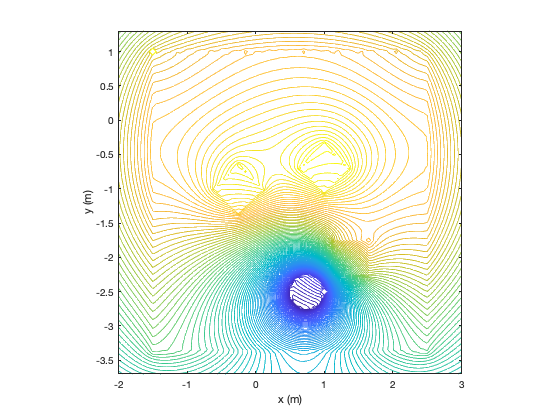

contour(x, y, v, 100)
axis equal
xlabel("x (m)")
ylabel("y (m)")

quiver(x, y, fx, fy)
axis square
xlim([-2 3])
ylim([-3.37 1.3])
xlabel("x (m)")
ylabel("y (m)")